# Battery circuit model parameters estimation using impedance data

This demo uses measured impedance data to estimate the parameters needed by a battery **Equivalent Circuit Model (ECM)**, parameters that can be used for instance in a Simscape™ Battery™ block.

This is of interest due to the electrification megatrend, since typically battery model parameters are estimated using time domain data, and the estimation is typically slow. Additionally, the frequency content of the data measured in time domain may be limited. Using [Electrochemical impedance spectroscopy](https://pubs.acs.org/doi/10.1021/acsmeasuresciau.2c00070#:~:text=Electrochemical%20impedance%20spectroscopy%20(EIS)%20offers,biosensing%2C%20noninvasive%20diagnostics%2C%20etc.) (EIS) data to directly estimate model parameters is fast and the model may cover a broader frequency range. EIS is basically a frequency response estimation technique based on the perturbation of an electrochemical system in equilibrium or in steady state, via the application of a sinusoidal signal (AC voltage or current) over a wide range of frequencies and the monitoring of the sinusoidal response (current or voltage, respectively) of the system.

Demo contents:

- Discuss the practical frequency range for Li-ion Battery Impedance Spectroscopy

- Explain the Constant Phase Element (CPE)

- Define an electrical circuit for a battery model. The circuit uses CPEs .  Estimate circuit parameters using optimization techniques. Note that a CPE model cannot be simulated in Simulink<sup>®</sup> since it uses a fractional-order derivative.

- Estimating a no-CPE circuit transfer function using a regular linear ECM (such a model can be simulated in Simulink)

- Verify the no-CPE model in time domain, using Simscape™ Battery™

- Discuss advantages and disadvantages of CPEs for simulation

## Practical Frequency Range for Li-ion Battery Impedance Spectroscopy

Generally, the frequency range for impedance spectroscopy on Li-ion batteries spans from millihertz (mHz) to megahertz (MHz) . Below is a breakdown of the frequency ranges and the corresponding physical processes they represent (for more details, refer to Reference 1):

- **High Frequencies (10 kHz to 1 MHz or higher):**

- **Inductive effects and ohmic resistance:** At very high frequencies, typically above 10 kHz, the impedance response is dominated by the inductive effects of the cell leads and connectors, as well as the ohmic resistance of the electrolyte and the current collectors. The ohmic resistance (also called the bulk or solution resistance) is associated with the movement of ions in the electrolyte and the electronic resistance of the materials.

- **Intermediate Frequencies (1 Hz to 10 kHz):**

- **Charge transfer resistance and double-layer capacitance:** In the intermediate frequency range, the impedance spectrum typically shows a semicircle in the Nyquist plot, which corresponds to the charge transfer resistance at the electrode/electrolyte interface and the double-layer capacitance. The charge transfer resistance is related to the kinetics of the electrochemical reactions occurring at the electrode surfaces.

- **Solid electrolyte interphase (SEI) layer:** The properties of the SEI layer, which forms on the anode surface, can also be probed in this frequency range. The SEI layer affects the impedance response due to its resistive and capacitive characteristics.

- **Low Frequencies (0.01 Hz to 1 Hz):**

- **Diffusion processes (Warburg impedance):** At low frequencies, the impedance response is influenced by the diffusion of lithium ions within the electrode materials, especially in the solid phase. This is often seen as a linear region with a slope of 45 degrees in the Nyquist plot, known as the Warburg impedance. It reflects the solid-state diffusion of lithium ions in the active material.

- **Battery relaxation and other slow processes:** Very low frequencies can capture relaxation processes and other slow dynamic phenomena within the battery, such as the redistribution of ions and the stabilization of the SEI layer over longer timescales.

While all three frequency ranges (low, intermediate, and high) provide valuable information, the intermediate frequency range (1 Hz to 10 kHz) is the most important from an application viewpoint due to its relevance to charge transfer resistance, SEI layer characterization, diagnostics, and battery management. This range directly impacts the efficiency, performance, and longevity of Li-ion batteries in real-world applications.

## Load impedance measurements

% Load "measured" EIS data: realZ, imaginaryZ, frequency vector in rad/s.
% Note: The data is synthetically generated, using makeEISdata.mlx
% MATLAB program

load("ImpedanceData.mat","imZ","reZ","freq");

% "Measured" impedance data
measReZ = reZ; % real part of Z
measImZ = imZ; % imaginary part of Z


## Define a battery model that uses CPE elements

The constant phase element (CPE) is a useful model element in electrochemical impedance spectroscopy (EIS) that describes the behavior of non-ideal capacitive systems. In many cases, real systems don't perfectly adhere to the ideal behavior of an ideal capacitor, especially at high frequencies or in the presence of rough or porous surfaces. The CPE model helps to account for these deviations.

In the context of electrochemical systems, the impedance (Z) of a CPE can be described as:


$$Z(\omega )=\frac{1}{(j\omega )^{\alpha } C_{\textrm{CPE}} }$$


Where:

- $Z(\omega )$ is the complex impedance at frequency $\omega$

- $j\;$is the imaginary unit

-$\omega \;$ is the angular frequency  in rad/s

-$\alpha \;$ is the phase exponent, which is a measure of non-ideality (0 ≤$\alpha$≤ 1)

-$C_{\textrm{CPE}} \;$ is the CPE constant, which represents the effective capacitance of the CPE

The phase exponent,$\;\alpha \;$, differentiates the CPE from an ideal ideal capacitor. When $\alpha \;$= 1, the CPE reduces to an ideal capacitor. As $\alpha \;$decreases from 1, the CPE behaves more and more like an ideal capacitor at low frequencies. When$\alpha \;$= 0, the CPE becomes an ideal resistor. 

The constant phase element model is particularly useful for describing complex interfaces, such as porous electrodes or electrodes with rough surfaces, where the impedance behavior deviates from the ideal capacitive behavior. It allows for a more accurate representation of these systems in impedance spectroscopy analysis.

We consider the following battery model :

### 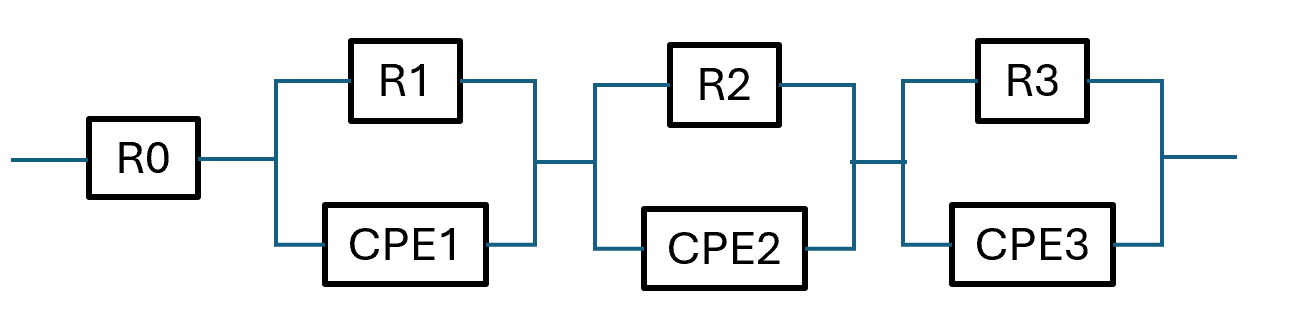

The impedance of this electric circuit can be written as:

where:

- **Tau = R*C** represents the time constant of the R-CPE parallel circuit.

- **1i** is the imaginary unit symbol

- **freq** is the frequency vector in rad/s

- **CPEfactor** is the exponent of the fractional-order derivative

The parameters to be estimated are **R1..3, Tau1..3, and CPE1..3 factors**.

### Battery model parameter estimation

Optimization using nonlinear least-squares algorithm (implemented by [lsqnonlin](https://www.mathworks.com/help/optim/ug/lsqnonlin.html)) can be used to quickly estimate the parameters of an arbitrary circuit model. The cost function used by the optimizer is defined in the local function **costFcn**. One thing to note is that a penalty is used to penalize negative params or time constants not in ascending order. The penalty is used as a soft constraint in the cost definition. 

% we assume that R0 is where ImZ is closest to zero, so R0 is not estimated using optimization

% Find the index of the measImZ value closest to zero
[~, idx] = min(abs(measImZ));
R0 = measReZ(idx)

R0 = 0.0150

% Define initial parameters for the optimization
init_params = [
    R0      % R0
    0.005   % R1
    0.01    % R2
    0.02    % R3
    1       % Tau1
    5       % Tau2
    10      % Tau3
    0.5     % CPE1 factor
    0.5     % CPE2 factor
    0.5     % CPE3 factor
    ];

% Search bounds (lower bound, upper bound)
lb =  [R0, 1e-3, 1e-3, 1e-3, 1e-6, 1e-6, 1e-6, 0, 0, 0];
ub =  [R0, 1, 1, 1, Inf, Inf, Inf, 1, 1, 1];

% Optimization cost function weights
weights = ones(1,length(freq)); % default

% Define weighting function, so that intermediate frequency range is emphasized
% More weight for the frequency range of interest: 1 Hz to 10 kHz
low_threshFreq_Hz = 1; % Hz
hi_threshFreq_Hz = 1e4; % Hz
weights((2*pi*low_threshFreq_Hz<freq)<2*pi*hi_threshFreq_Hz) = 10;

% Parameter estimation

% make results reproducible
rng("default")

% lsqnonlin solver options
lsqOptions = optimoptions(@lsqnonlin);
lsqOptions.Algorithm = "trust-region-reflective"; 
lsqOptions.FiniteDifferenceType = "central";
lsqOptions.Display = "final"; % "none" "iter" "final"
lsqOptions.MaxIterations = 1e5;
lsqOptions.MaxFunctionEvaluations = 1e6;
lsqOptions.FunctionTolerance = 1e-8;
lsqOptions.OptimalityTolerance = 1e-8;
lsqOptions.StepTolerance = 1e-8;

tic
[estimated_params,cost,exitflag,output] = lsqnonlin(...
    @(params) costFcn(params, measReZ, measImZ, freq, weights),...% cost function
    init_params,...%initial parameters for the optimization
    lb,ub,...% Search bounds (lower bound, upper bound)
    lsqOptions);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


elapsedTime = toc

elapsedTime = 1.1314

% Extract parameters
R0 = estimated_params(1);
R1 = estimated_params(2);
R2 = estimated_params(3);
R3 = estimated_params(4);
Tau1 = estimated_params(5);
Tau2 = estimated_params(6);
Tau3 = estimated_params(7);
CPE1factor = estimated_params(8);
CPE2factor = estimated_params(9);
CPE3factor = estimated_params(10);

% Display estimated parameters
fprintf('Estimated parameters: [');

Estimated parameters: [

fprintf('%.4f ', estimated_params);

0.0150 0.0020 0.0207 0.2241 0.0022 15.3804 7509.2467 0.7846 0.5995 0.9448 

fprintf(']\n');

]


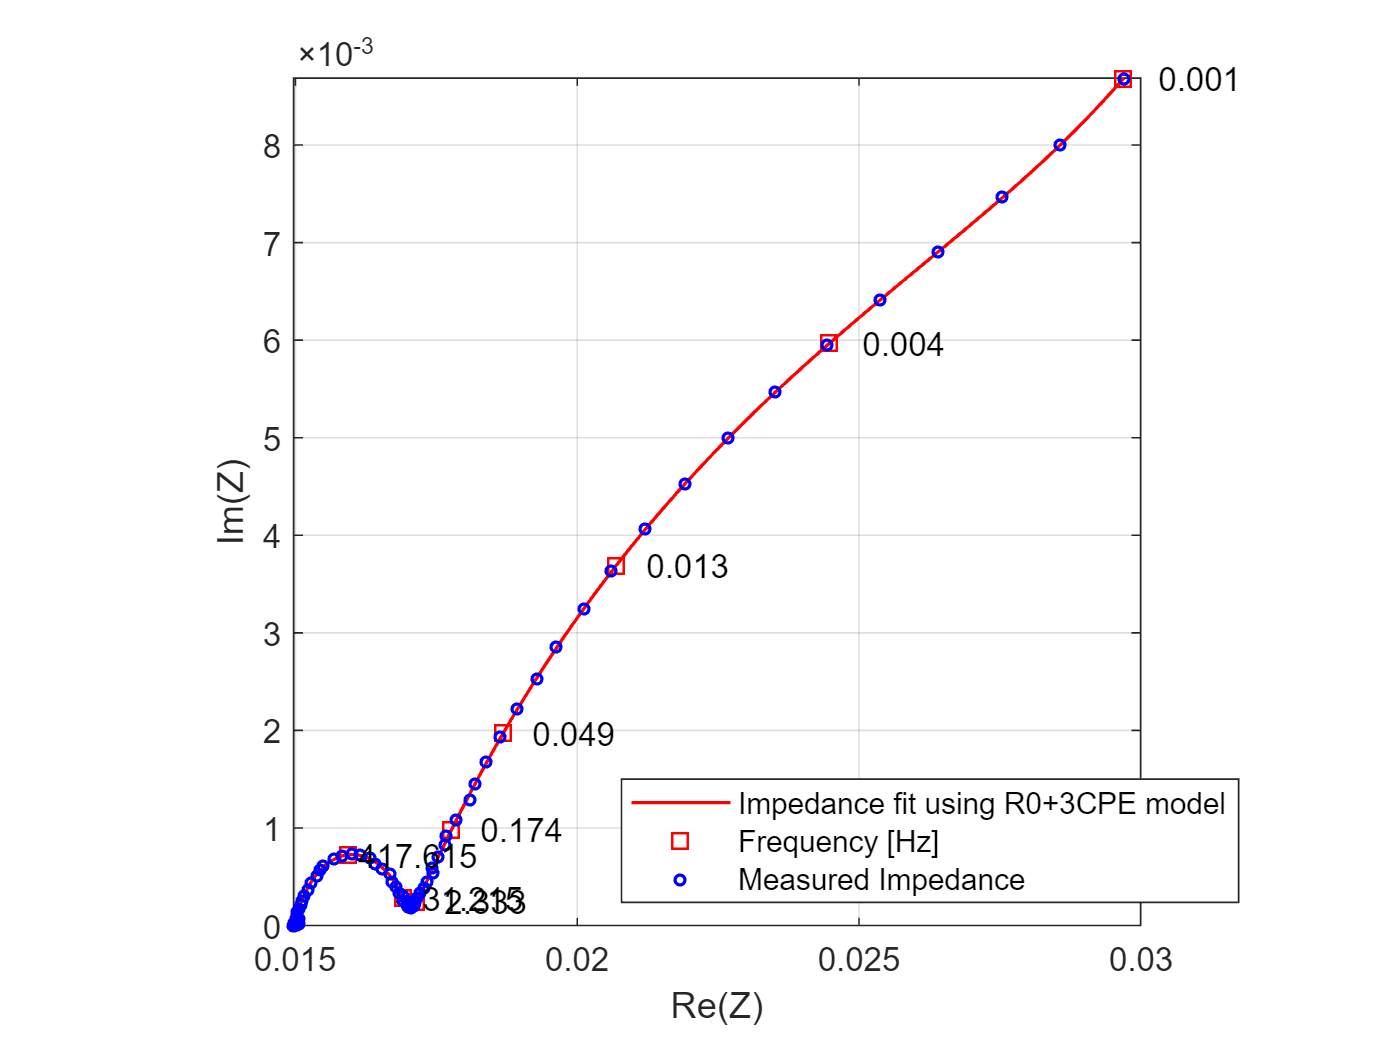

plotImpedance(measReZ,measImZ,freq,R0,R1,R2,R3,Tau1,Tau2,Tau3,CPE1factor,CPE2factor,CPE3factor)
% Numbers on the plot represent the frequency in Hz.
legend("Impedance fit using R0+3CPE model","Frequency [Hz]", "Measured Impedance","Location","best")

As seen from the figure, the fit is very good. However, the main disadvantage of using a CPE-based model is that it cannot be simulated in Simulink. One could try to use a software like [FOMCON](https://www.mathworks.com/matlabcentral/fileexchange/66323-fomcon-toolbox-for-matlab?s_tid=ta_fx_results), which is toolbox for MATLAB dedicated to fractional-order modeling and control of dynamic systems. FOMCON allows to transform a fractional-order derivative into a regular derivative that can be used in Simulink, by using [Oustaloup filters](https://fomcon.net/fo/fractional-order-modeling/). This is a relatively difficult task that may not increase the accuracy of the fit. Instead, we will next directly fit a regular linear transfer function (that do not use CPEs) to the impedance data.

## Estimate a no-CPE circuit transfer function (using a regular linear ECM)

This time we use a regular R0 + 3 (R-C) linear ECM. Such models are used typically for Li-Ion cell modeling and the estimated parameters can be directly used in the blocks used by the Simscape Battery product, as described further below. However, for the purpose of fitting and using the model in MATLAB only, if needed, the model can be changed by using the circuit impedance equation defined in the function **paramEstimFcn**.

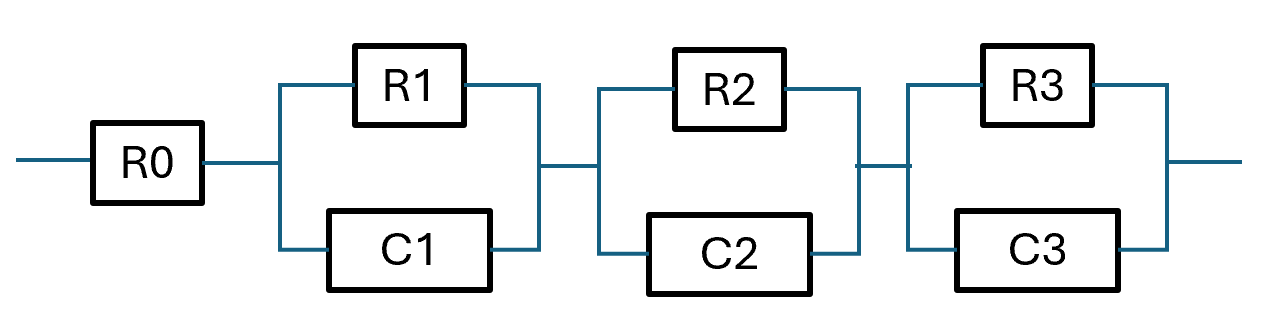

The impedance of this electric circuit can be written as:

% Define initial parameters for the optimization (note that CPEfactors are
% set to 1, representing an ideal capacitor)
init_params_linear = [
    R0      % R0
    0.005   % R1
    0.01    % R2
    0.02    % R3
    1       % Tau1
    5       % Tau2
    10      % Tau3
    1       % CPE1 factor
    1       % CPE2 factor
    1       % CPE3 factor
    ];

% Search bounds (lower bound, upper bound)
lb =  [R0, 1e-3, 1e-3, 1e-3, 1e-6, 1e-6, 1e-6, 1, 1, 1];
ub =  [R0, 1, 1, 1, Inf, Inf, Inf, 1, 1, 1];

% Optimization cost function weights
weights = ones(1,length(freq)); % default

% Define weighting function, so that intermediate frequency range is emphasized
% More weight for the frequency range of interest: 1 Hz to 10 kHz
low_threshFreq_Hz = 1; % Hz
hi_threshFreq_Hz = 1e4; % Hz
weights((2*pi*low_threshFreq_Hz<freq)<2*pi*hi_threshFreq_Hz) = 10;

tic
[estimated_params_linear, resnorm_linear, residual_linear, exitflag_linear, output_linear] = lsqnonlin(...
    @(params) costFcn(params, measReZ, measImZ, freq, weights),...% cost function
    init_params_linear,...% initial parameters for the optimization
    lb,ub,...% Search bounds (lower bound, upper bound)
    lsqOptions);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


elapsedTime = toc

elapsedTime = 0.1460


% Extract parameters
R0 = estimated_params_linear(1);
R1 = estimated_params_linear(2);
R2 = estimated_params_linear(3);
R3 = estimated_params_linear(4);
Tau1 = estimated_params_linear(5);
Tau2 = estimated_params_linear(6);
Tau3 = estimated_params_linear(7);

% Display estimated parameters
fprintf('Estimated parameters: [');

Estimated parameters: [

fprintf('%.4f ', estimated_params_linear);

0.0150 0.0023 0.0059 0.0161 0.0005 9.6655 161.9101 1.0000 1.0000 1.0000 

fprintf(']\n');

]


Plot impedance:

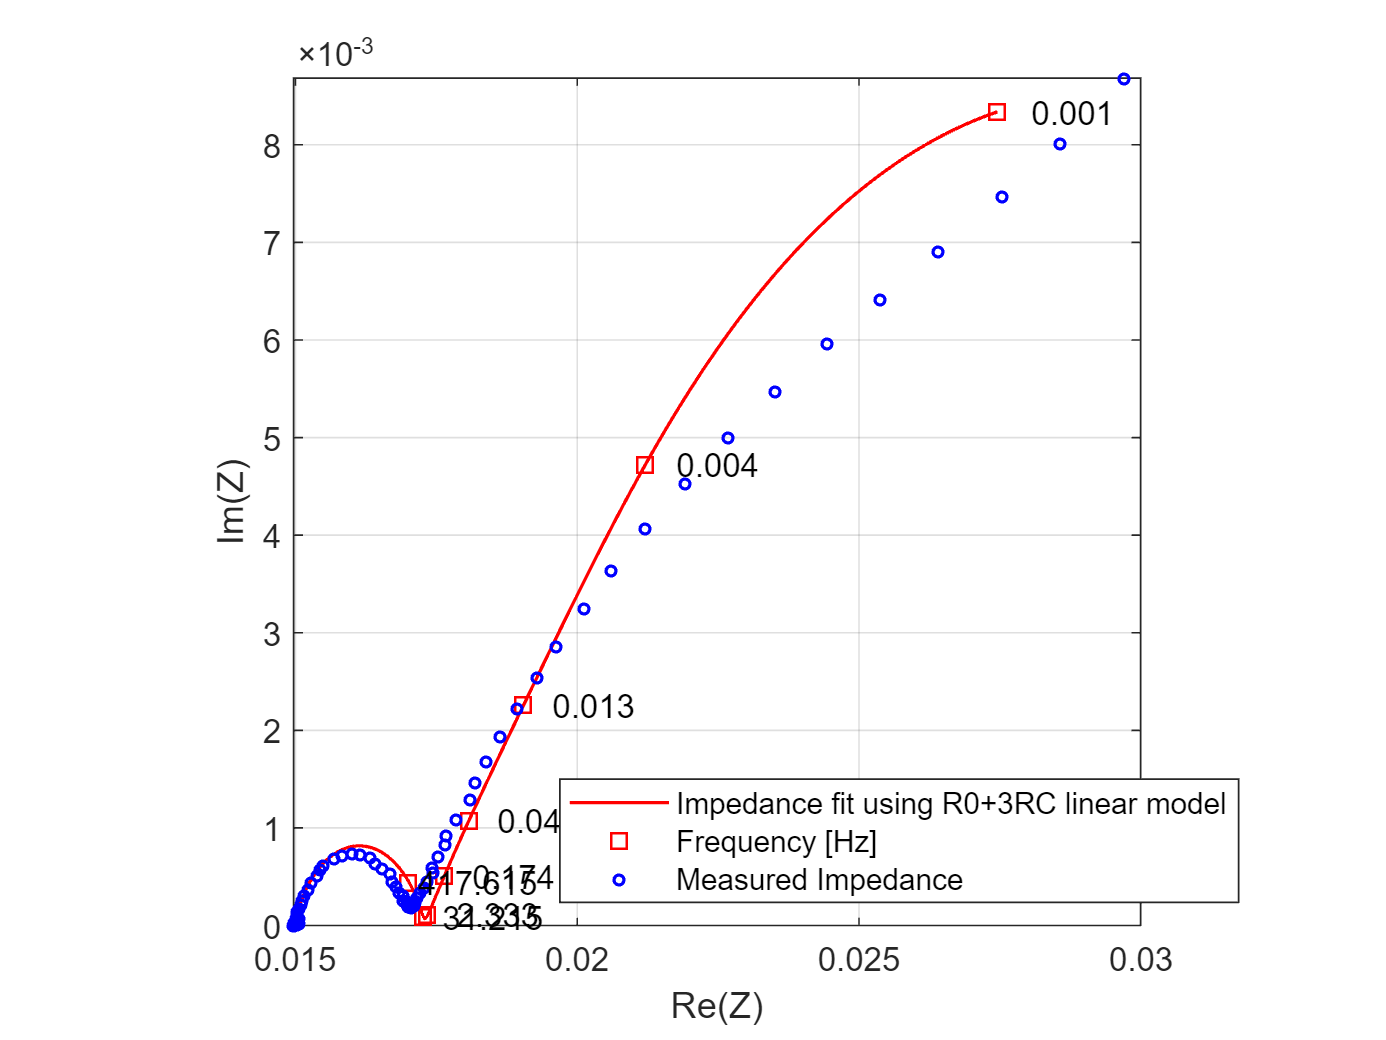

plotImpedance(measReZ,measImZ,freq,R0,R1,R2,R3,Tau1,Tau2,Tau3,CPE1factor,CPE2factor,CPE3factor)
legend("Impedance fit using R0+3RC linear model","Frequency [Hz]", "Measured Impedance","Location","best")

The linear system approximation for the impedance data is not as good as the nonlinear CPE-based model, as expected. Nevertheless, the fit quality in the intermediate frequency range (1 Hz to 10 kHz) is satisfactory. And, by tweaking the optimization settings, the weights used in the cost function, or by increasing the number of R-C pairs, it could be possible to obtain even better results. One thing that can cause concern is the difference in the R and Tau parameters obtained by the CPE-based and no-CPE models, however, the values for the CPE-based model are difficult to interpret since they correspond to non-ideal elements.

A major advantage of estimating parameters from frequency domain data is that the parameter estimation is very fast, much faster than estimating parameters from time series data. As it can be seen from the results above, parameter estimation takes less than 0.02 s on a typical laptop PC. A batch parameter estimation program can be created to process impedance values collected at various SOC and temperatures values of the battery cell, so that cell model parameters can be represented as (SOC,Temperature) look-up tables, and used for instance in the [Simscape Battery (Table-Based) model](https://www.mathworks.com/help/simscape-battery/ref/batterytablebased.html). For a typical measurement scenario, where the battery cell is tested at 50 different SOC values and at 10 different ambient temperatures, one would need to perform 50 x 10 = 500 calculations. Considering 0.02 s for each test, a full battery cell characterization can be finished in about 10 s, extremely fast compared to estimation using time domain data.

## Check the linear model, using Simulink and Simscape

We can check the linear R0 + 3RC model in simulation, using **battCircuit** Simulink model. The battery cell model uses the estimated parameters (for details about the model block, please refer to the [Behavioral battery model](https://www.mathworks.com/help/releases/R2023b/simscape-battery/ref/battery.html) documentation page).

We apply a pulse load current of 10 A and observe the dynamics of the battery voltage. The results show the expected dynamic behavior of a typical Li-Ion battery cell.

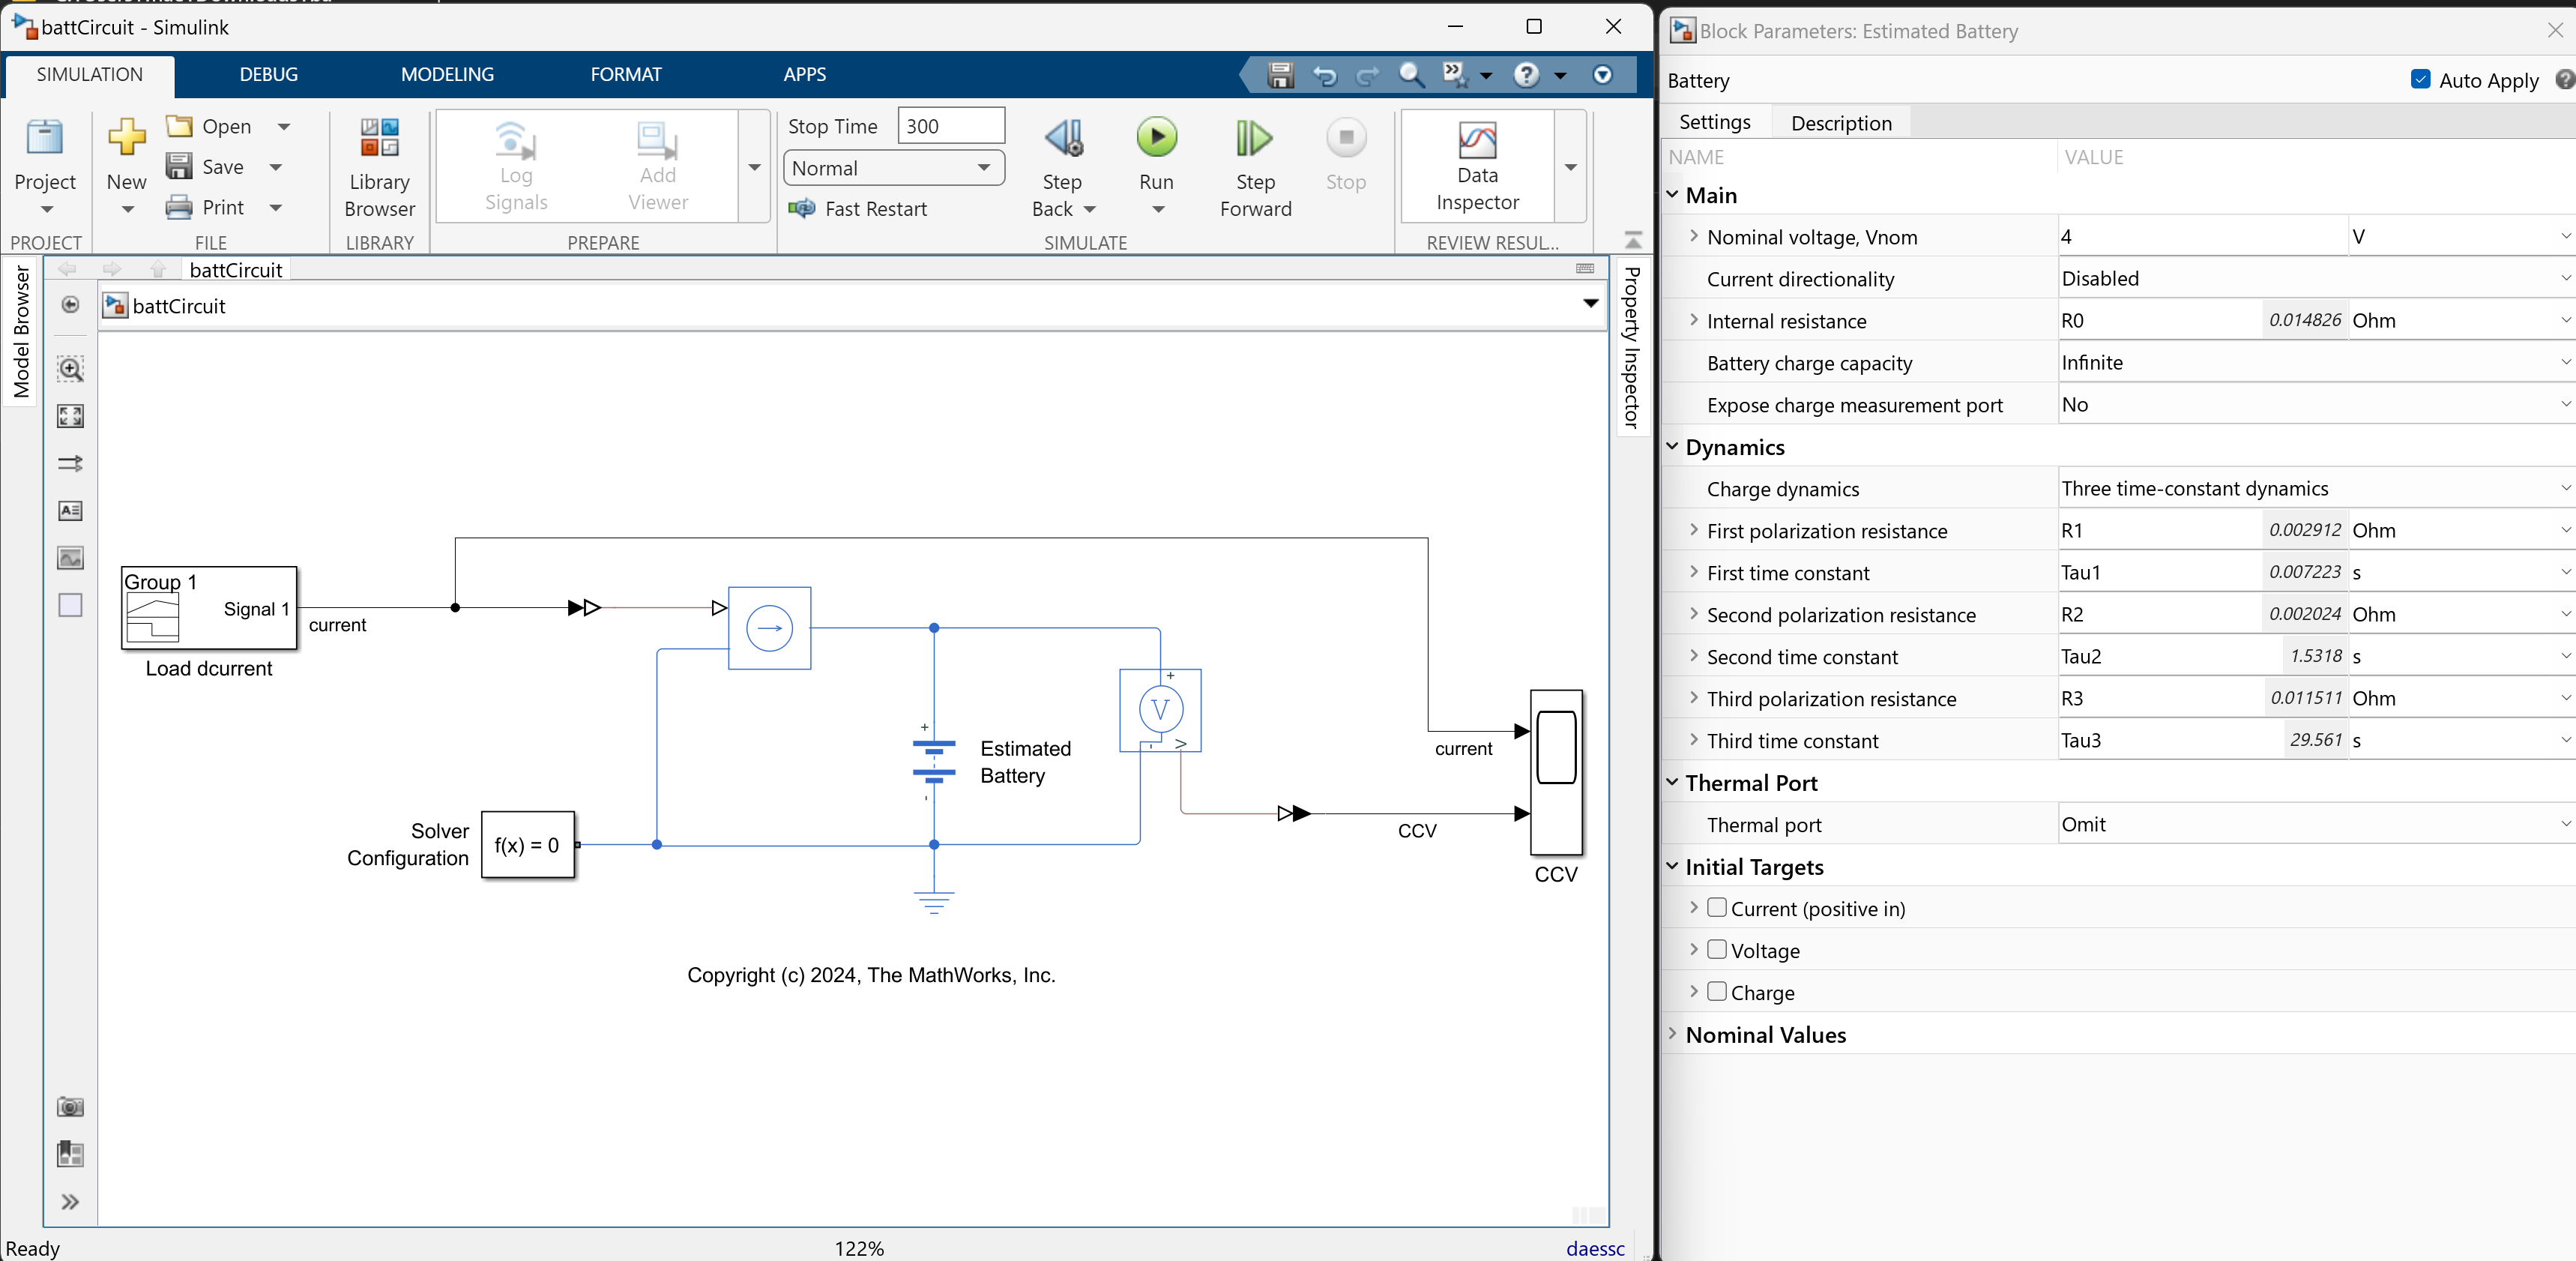

% Note: The user should have the Simulink model 'battCircuit' prepared with the estimated parameters
mdl = "battCircuit";
open_system(mdl);
sim(mdl);
open_system(mdl+"/CCV")


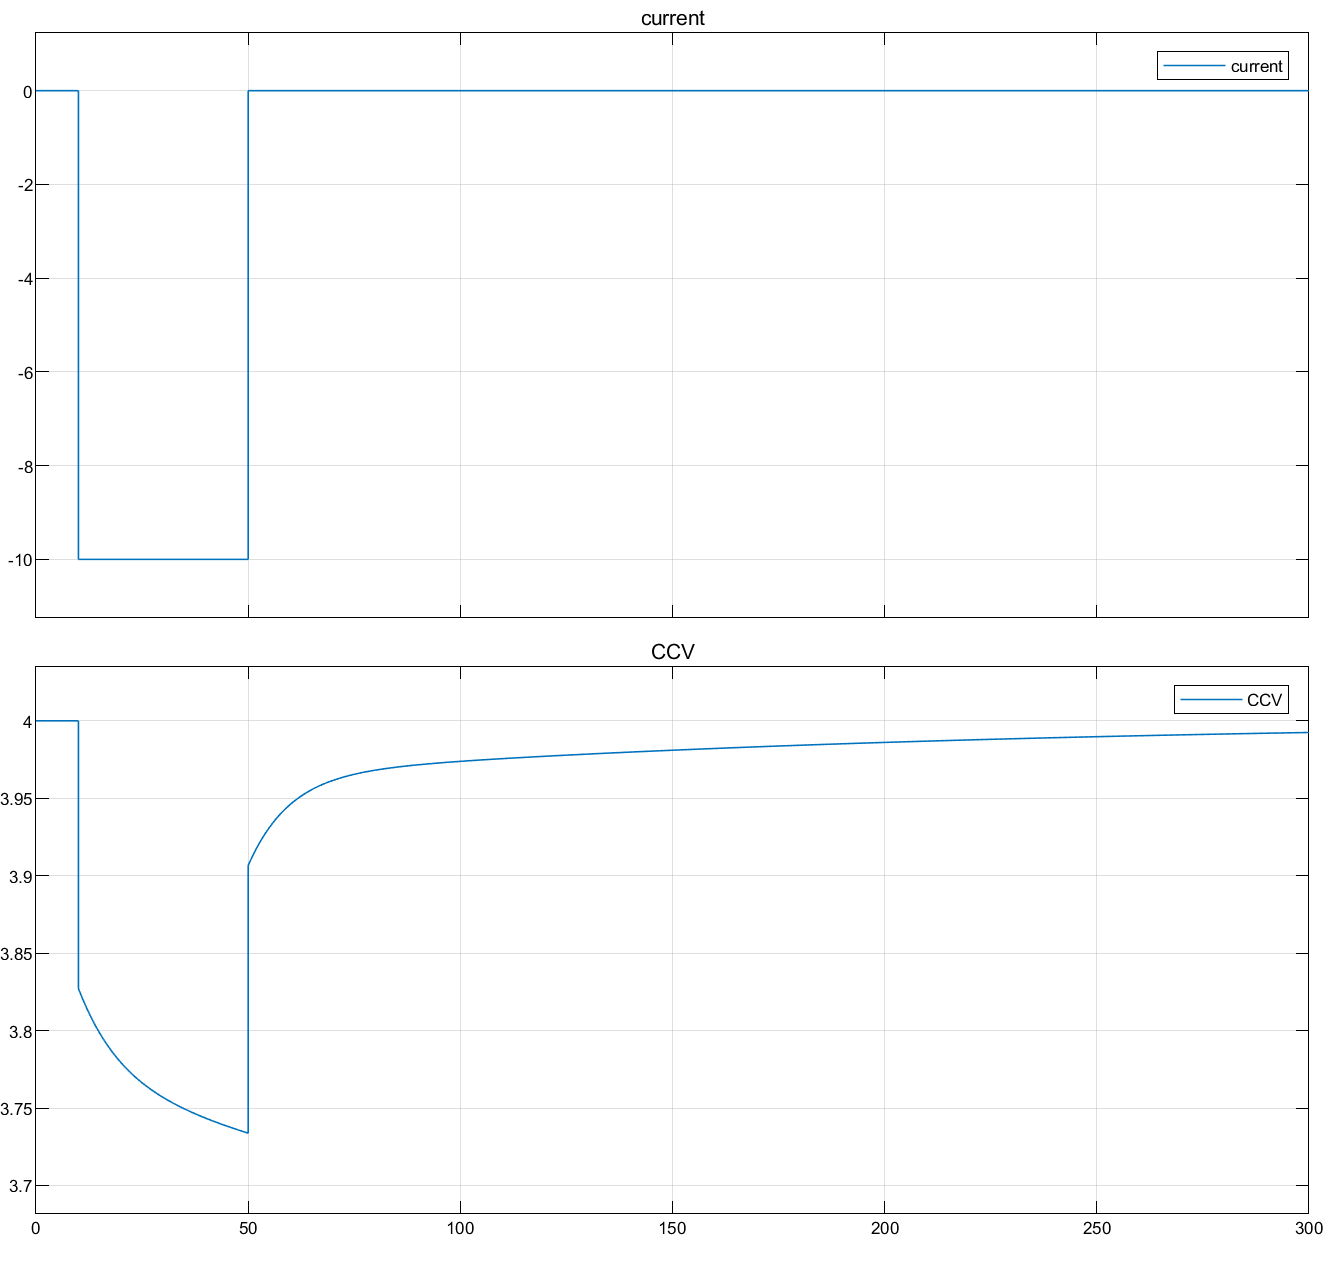

## Conclusions

- A linear RC pair element needs only two parameters, the R and C values, and the model can be described by a regular transfer function which can be simulated in Simulink. In contrast, if we consider an R-CPE pair, in order to simulate the model in Simulink, we need to transform the CPE element into a regular transfer function. Depending on the order of the approximation, one may need a relatively high-order transfer function to accurately represent a CPE element. This makes the usage of CPE problematic, especially when someone is interested in quickly estimating parameters for a typical linear circuit model.

- Until Simulink will natively support fractional-order derivatives (to properly model CPE elements), we believe that directly fitting a linear model is more preferable, as it is easier to use the model in the Simscape Battery blocks.

- Optimization using nonlinear least-squares algorithm (implemented by [lsqnonlin](https://www.mathworks.com/help/optim/ug/lsqnonlin.html)) can be used to quickly estimate the parameters of an arbitrary circuit model, much faster compared to estimation using time domain data.

## **MathWorks**®** products needed to run the demo**

- MATLAB® version R2023b or newer

- Simulink®

- Optimization Toolbox™

- Control System Toolbox™

- Simscape™

- Simscape™ Battery™

## **References**

1. P. Liu, G. Ning, and B. Haran, "Frequency Response Analysis of Lithium-Ion Batteries," Journal of The Electrochemical Society, vol. 151, no. 12, pp. A1969-A1973, 2004.

2. [Constant phase element - Wikipedia](https://en.wikipedia.org/wiki/Constant_phase_element) (retrieved at April 4 2024)

3. [FOMCON Toolbox for MATLAB](https://www.mathworks.com/matlabcentral/fileexchange/66323-fomcon-toolbox-for-matlab) (retrieved at April 4 2024)

4. [Oustaloup-Recursive-Approximation for Fractional Order Differentiators](https://www.mathworks.com/matlabcentral/fileexchange/3802-oustaloup-recursive-approximation-for-fractional-order-differentiators) (retrieved at April 4 2024)

## Helper functions

function cost = costFcn(params, measReZ, measImZ, freq, weights)
% Define cost function for parameter estimation

% Extract parameters
R0 = params(1);
R1 = params(2);
R2 = params(3);
R3 = params(4);
Tau1 = params(5);
Tau2 = params(6);
Tau3 = params(7);
CPE1factor = params(8);
CPE2factor = params(9);
CPE3factor = params(10);

% Calculate impedance model
Z_model = R0 + ...
    R1 ./ (1 + Tau1 * (freq * 1i) .^ CPE1factor) + ...
    R2 ./ (1 + Tau2 * (freq * 1i) .^ CPE2factor) + ...
    R3 ./ (1 + Tau3 * (freq * 1i) .^ CPE3factor);

% Separate real and imaginary parts
modelReZ = real(Z_model);
modelImZ = imag(Z_model);

% Define penalty for negative parameters or non-ascending time constants
penalty = 0;
if any(params < 0) || Tau1 > Tau2 || Tau2 > Tau3
    penalty = 1e6;
end

% Calculate cost function
cost = [weights .* (modelReZ - measReZ); weights .* (modelImZ - measImZ)] + penalty;
end

function  plotImpedance(measReZ,measImZ,freq,R0,R1,R2,R3,Tau1,Tau2,Tau3,CPE1factor,CPE2factor,CPE3factor)

% resample the frequencies with higher resolution, for better quality plot
freq = logspace(log10(freq(1)),log10(freq(end)),10*length(freq))';% Hz

% Circuit Impedance
Z = R0 + ...
    R1./(1 + Tau1*(freq*1i).^CPE1factor) + ...
    R2./(1 + Tau2*(freq*1i).^CPE2factor) +...
    R3./(1 + Tau3*(freq*1i).^CPE3factor) ;

reZ = real(Z);
imZ = imag(Z) ;

% The Nyquist plot (also known as the Cole-Cole plot) is a graph that plots
% impedance values measured at multiple frequencies.

figure;
plot(reZ,-imZ,"r",DisplayName="Model",LineWidth=1)
hold on
% do not plot all frequency values, plot becomes cluttered
endFreq = 1e5/2/pi; % Hz
[~, endfreq_idx] = min(abs(freq - endFreq));
dispFreq = [1:50:160, 200:100:endfreq_idx];
plot(reZ(dispFreq),-imZ(dispFreq),"rs",DisplayName="Frequency [Hz]",LineWidth=1)
plot(measReZ,-measImZ, "bo",MarkerSize = 3, DisplayName="Measured",LineWidth=1)
text(reZ(dispFreq)*1.01,-imZ(dispFreq),num2str((1/2/pi)*freq(dispFreq),'  %.3f'))
ylim([0,inf])
axis("square")
grid on
xlabel('Re(Z)'), ylabel('Im(Z)')
legend("show","Location","best")

end

*Copyright 2024, The MathWorks, Inc.*